**ECE 101 - Arrays and Matricies**

Michael Dekoski

4-11-23

clear
clc

Practice for Arrays and Matricies

rowVect = [32, 15, 64, 10, 100];
score = rowVect(1);     % gets item at index 1
score2 = rowVect(4);    % gets item at index 4
rowVect(6:10) = [92, 165, 147, 345, 685]; % concatination
rowVect2 = [1:1.6:10];   % auto vector generation
rowVect2(2) = 5;     % replace in array
rowVect3 = linspace(0, 100, 18);    %

colVect = [456; 17; 562; -415];
number = colVect(3);
colVect2 = rowVect2';
colVect2(4) = 20;
colVect3 = linspace(23.2, 76.5, 20)';

rowVectCom = [rowVect, rowVect3];    % concat 2 vectors

Timer in MatLab

startTime = clock

startTime = 1.0e+03 *

    2.0230    0.0040    0.0110    0.0140    0.0340    0.0050


stopTime = clock

stopTime = 1.0e+03 *

    2.0230    0.0040    0.0110    0.0140    0.0400    0.0384


This is measure of time

Turn everything (reasonable into seconds)

% vector into seconds
startSec = startTime(6) + (startTime(5)*60) + (startTime(4)*3600);

stopSec = stopTime(6) + (stopTime(5)*60) + (stopTime(4)*3600);

timeInHours = (stopSec - startSec)/3600;

hour = floor(timeInHours)

hour = 0


hourRem = timeInHours - hour;

timeInMinutes = hourRem * 60;

min = floor(timeInMinutes)

min = 6


minRem = timeInMinutes - min;

sec = minRem * 60

sec = 33.4490

2-D Arrays

twoDArray = [2, 4, 6;...
            -3, 35, 657;...
            648, 341, -874];

twoDNum = twoDArray(3,2);
twoDRow = twoDArray(3,:);
twoDcol = twoDArray(:,2);
matOut2D = twoDArray(2:3, 1:2)

matOut2D =     -3    35
   648   341



twoDArray(4, :) = [45, 612, 1];
twoDArray(:, 4) = [-67; 5; 561; 763];

mat2 = rand(4,3)

mat2 =     0.8147    0.6324    0.9575
    0.9058    0.0975    0.9649
    0.1270    0.2785    0.1576
    0.9134    0.5469    0.9706


mat3 = ones(3,4)

mat3 =      1     1     1     1
     1     1     1     1
     1     1     1     1


mat4 = zeros(5,6)

mat4 =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



mat4(2:4, 2:5) = mat3

mat4 =      0     0     0     0     0     0
     0     1     1     1     1     0
     0     1     1     1     1     0
     0     1     1     1     1     0
     0     0     0     0     0     0



vertWall = ones(1,4)'

vertWall =      1
     1
     1
     1



diagWall = eye(5)

diagWall =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


rot90(diagWall)

ans =      0     0     0     0     1
     0     0     0     1     0
     0     0     1     0     0
     0     1     0     0     0
     1     0     0     0     0


Topographical Map

topoMap = ones(9, 7)*5

topoMap =      5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5
     5     5     5     5     5     5     5


topoMap(2:3,2:3) = ones(2,2)*10;
topoMap(7:8,5:6) = zeros(2,2);

mountEastSlope = linspace(10,5,5);
topoMap(2,3:7) = mountEastSlope;
topoMap(3,3:7) = mountEastSlope

topoMap =     5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    5.0000   10.0000   10.0000    8.7500    7.5000    6.2500    5.0000
    5.0000   10.0000   10.0000    8.7500    7.5000    6.2500    5.0000
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    5.0000    5.0000    5.0000    5.0000         0         0    5.0000
    5.0000    5.0000    5.0000    5.0000         0         0    5.0000
    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000


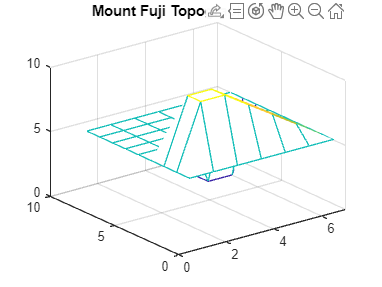


figure(1)
mesh(topoMap)
title('Mount Fuji Topographical map')

Why strings are sort of like arrays?

str = 'Matrix Math'

str = 'Matrix Math'

letter = str(8)

letter = 'M'